# Homework 1 Problem 3.51

clear; clc; close;

## Plotting Parameters

n_pointsPlot = 16^2; % number of points to plot (preferably a suqare number)
% plotting window
d_o_rangePlot = [0, 5]; % plotting range of d_0 (min, max)
t_rangePlot = [0, .3]; % plotting range of t (min, max)


## Define Constants

h = 10; % hieght of tank (m)
H = 30; % elevation of bottom of tank from ground (m)
D = 10; % diameter of tank (m)
w = 7e2; % distriubuted wind load (N/m^2)
e = 1e-1; % ecentricity (m) - assumed worst case
gamma_w = 1e4;  % specific weight of water (N/m^3)
gamma_s = 80e3;  % specific weight of steel (N/m^3)
E = 210e9; % modulus of elasticity (Pa)
t_t = 1.5e-2; % tank thickness (m)
g = 9.81;  % gravitational acceleration (m/s^2)

% constraints
Delta = 2e-2; % allowable deflection (m)
sigma_b = 165e6; % bending stress alowable (Pa)
R_i_min = .35; % minimum inner radius (m)
R_i_max = 2.0; % minimum outer radius (m)
t_min = 1.0e-2; % minimum wall thickness (m)
t_max = 20e-2; % maximum wall thickness (m)

## Calculate Unkown Constants

V = 1.2 * pi * D^2 * h; % tank volume (m^3)
A_s = 1.25 * pi * D^2; % tank surface area (m^2)
A_p = 2/3 * D * h; % projected tank area (m^2)
P = V*gamma_w + t_t*A_s*gamma_s; % axial load on column due to weight of tank (N)
W = w*A_p; % lateral load on column due to wind (N)

% constant related to delfection
c_delta = W*H^2/(12*E) * (4*H+3*h) + H/(2*E) * (.5*W*h+P*e) * (H+h);

## Configure Plotting Parameters

% construct vectors containg the all values of d_o and t to be plotted
d_o_range = linspace(d_o_rangePlot(1), d_o_rangePlot(2), floor(sqrt(n_pointsPlot)));
t_range = linspace(t_rangePlot(1), t_rangePlot(2), floor(sqrt(n_pointsPlot)));

% construct a grid of points to plot
[d_o_grid, t_grid] = meshgrid(d_o_range,t_range);

## Produce level curves of cost function

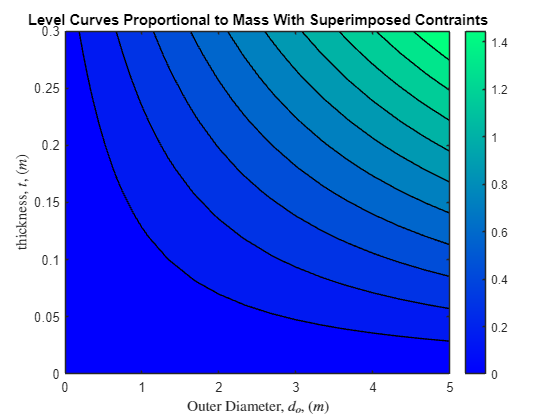

% compute cost
f = cost(d_o_grid,t_grid);

% plot level curves of cost
contourf(d_o_grid, t_grid, f, 10, "LineWidth",.001), colormap("winter"); set(gca, "Color", [1,1,1]); colorbar;
title("Level Curves Proportional to Mass With Superimposed Contraints");
zlabel("cost, f, (m^2)",Interpreter="latex");
xlabel("Outer Diameter, $d_o$, $(m)$",Interpreter="latex");
ylabel("thickness, $t$, $(m)$",Interpreter="latex");
hold on;
xlim(d_o_rangePlot);ylim(t_rangePlot)

## Compute Constrain funtion values

%geometeric allowables

% inner radius
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [d_o_range-4, t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% outer radius
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [-d_o_range + .7, t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% max thickness radius
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [.2 * ones(1,length(t_range)), t_rangePlot(2) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% min thickness radius
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [.01 * ones(1,length(t_range)), t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% thickness to diameter ratio
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [d_o_range/92, t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% Load Based Allowables

%Deflection

% delfection allowables equations
% d_o_range./2 - (-(64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta))).^(1/2)./8).^(1/2)./2
% d_o_range./2 + (-(64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta))).^(1/2)./8).^(1/2)./2
% d_o_range./2 - ((64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta))).^(1/2)./8).^(1/2)./2
% d_o_range./2 + ((64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta))).^(1/2)./8).^(1/2)./2

% at our value of Delta
% d_o_range./2 - (-(64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2
% d_o_range./2 + (-(64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2
%  d_o_range./2 - ((64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2
%  d_o_range./2 + ((64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2

% nonphysical
% boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
% boundrayEdges_Ycoords = [d_o_range./2 - (-(64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2, t_rangePlot(2) * ones(1,length(t_range))];
% fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% nonphysical
% boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
% boundrayEdges_Ycoords = [d_o_range./2 + (-(64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2, t_rangePlot(1) * ones(1,length(t_range))];
% fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% disallows beneath
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [d_o_range./2 - ((64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2, t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])


% disallows above
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [d_o_range./2 + ((64*d_o_range.^4 - (12675364185389375*pi)/18014398509481984).^(1/2)/8).^(1/2)./2, t_rangePlot(2) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

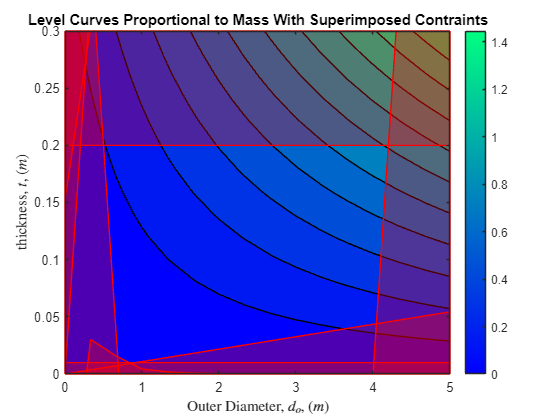


% delfection allowables + pert
% bounded from beneath
% boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
% boundrayEdges_Ycoords = [d_o_range./2 - ((64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta-.1))).^(1/2)./8).^(1/2)./2, t_rangePlot(1) * ones(1,length(t_range))];
% fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
% boundrayEdges_Ycoords = [d_o_range./2 + ((64.*d_o_range.^4 - (507014567415575*pi)./(36028797018963968.*(Delta-.1))).^(1/2)./8).^(1/2)./2, t_rangePlot(1) * ones(1,length(t_range))];
% fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])


beta = 2*sigma_b * ( -46*P*H/(pi*E) * d_o_range - (W*(H+.5*h)+e*P)/2*sigma_b ); % parameter for stress calculations

% First of two stress allowables
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [( -d_o_range + (d_o_range.^4 - 64/pi * P*c_delta./beta).^(1/4) )/-2, t_rangePlot(1) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

% second of two stress allowables
boundrayEdges_Xcoords = [d_o_range, fliplr(d_o_range)];
boundrayEdges_Ycoords = [( -d_o_range - (d_o_range.^4 - 64/pi * P*c_delta./beta).^(1/4) )/-2, t_rangePlot(2) * ones(1,length(t_range))];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0], "FaceAlpha",.3, "EdgeColor",[1,0,0])

xlim(d_o_rangePlot);ylim(t_rangePlot)

function f = cost(d_o, t)
    % cost function (to be minimized)
    f = t .* (d_o + t);
end